# Enzyme kinetics within our GRASP: A computational platform for building kinetic models of cellular metabolism

**Marta R. A. Matos, Pedro A. Saa, Nicholas Cowie, Svetlana Volkova, Marina de Leeuw, Lars K. Nielsen**

The aim of this tutorial is to illustrate the execution and use of GRASP for building and analyzing kinetic models of metabolism. This tutorial demonstrates how to build an ensemble of models for a fairly large system and perform Metabolic Control Analysis (MCA) on the resulting ensemble. Model ensembles built with GRASP are particularly suitable to perform MCA. 

Inspired in *E. coli*'s central carbon metabolism, the model is composed by a total of 61 reactions, where 19 of those are either exchange reactions (to allow metabolites to be exchanged with the cell's environment) or re-generation reactions to re-convert certain metabolites, .e.g. NAD/NADH, NADP/NADPH, ADP/ATP. These reactions are modeled by simple mass action rate laws, while the remaining 41 reactions are decomposed into microscopic reactions and each microscopic reaction is modeled by a mass action rate law. The model also includes two isoenzymes, PYK1 and PYK2, where we don't know how the flux is distributed by the two isoenzymes, and a promiscuous enzyme, G6PDH, which can use either NAD or NADP as co-factor. Finally the model includes several competitive inhibitors and allosteric effectors. See the kinetics sheet in the tutorial_05_large_scale in io/input for more details about the model.

## Tutorial 05: Sampling from the prior (GRASP mode)

Clear all variables and add functions to path.  Note that you need to be in the tutorials folder.

clear, close all
rng('default');                 % for reproducibility
addpath(fullfile('..', 'matlab_code', 'analysisFxns'), ...
        fullfile('..', 'matlab_code', 'ensembleFxns'), ...
        fullfile('..', 'matlab_code', 'patternFxns'));

Set the maximum number of models to sample. This is particularly important when simulating the model from the prior (i.e., no experimental data defined)

maxNumberOfSamples = 1e6;

Set a threshold for the minimum Jacobian eigenvalue of the system. Models with values below this threshold will be discarded due to unstability criteria.

eigThreshold = 1e-5;

Define the model ID name, input and output files. These paths are necessary for executing GRASP.

modelID = 'tutorial_05_large_scale';
inputFile  = fullfile('..', 'io', 'input', modelID);
outputFile = fullfile('..', 'io', 'output', [modelID, '.mat']);

Build the kinetic ensemble. In this case, we will build an ensemble of 10.000 models. To accelerate computations, we can set the parellel mode to 'on' in the specification file. If the parallel mode is not "on", the sampling is expected to take between 30min and 1h.

tic
ensemble = buildEnsemble(inputFile, outputFile, maxNumberOfSamples, eigThreshold);

General information loaded.
Flux data computed and loaded.
The fluxes and Gibbs energies are consistent.
Flux directions are consistent.
Gibbs energy directions are consistent.
The initial point obtained from TMFA is feasible and valid for starting the sampler.
Thermodynamic data computed and loaded.
Metabolomics data loaded.
No previous prior for model 1
Proteomics and exchange data loaded and consistent.
Kinetic information loaded and kinetic model built: Structure 1.
Ensemble structure ready.
Ensemble successfully initialized.
Sampling fluxes
Sampling Gibbs energies
Fluxes and Gibbs energies successfully sampled
Running initial sampler.
Sampling model: 1
Sampling model: 2
There are eigenvalues larger than 1e-05. Model ID: 2
Sampling model: 3
There are consistency problems during the reaction sampling. Model ID: 3
Sampling model: 4
Sampling model: 5
Sampling model: 6
Sampling model: 7
Sampling model: 8
Sampling model: 9
Sampling model: 10
Sampling model: 11
There are consistency prob

toc

Elapsed time is 14826.724862 seconds.


Using this ensemble, we compute flux and metabolite control coefficients and visualize the final results. Note that since the model includes promiscuous enzymes, we actually run the response analysis as well.

If saveMCAMatrices is set to 1, then the control/response coefficient matrices for each model will be saved. This might result in longer runtimes as it can occupy a large amount of memory. If saveMCAMatrices is set to 1, only the average control/response coefficients over the whole ensemble will be returned.

tic
saveMCAMatrices = 1;
mcaResults = controlAndResponseAnalysis(ensemble,saveMCAMatrices);

Model: 1
Model: 2
Model: 3
Model: 4
Model: 5
Model: 6
Model: 7
Model: 8
Model: 9
Model: 10
Model: 11
Model: 12
Model: 13
Model: 14
Model: 15
Model: 16
Model: 17
Model: 18
Model: 19
Model: 20
Model: 21
Model: 22
Model: 23
Model: 24
Model: 25
Model: 26
Model: 27
Model: 28
Model: 29
Model: 30
Model: 31
Model: 32
Model: 33
Model: 34
Model: 35
Model: 36
Model: 37
Model: 38
Model: 39
Model: 40
Model: 41
Model: 42
Model: 43
Model: 44
Model: 45
Model: 46
Model: 47
Model: 48
Model: 49
Model: 50
Model: 51
Model: 52
Model: 53
Model: 54
Model: 55
Model: 56
Model: 57
Model: 58
Model: 59
Model: 60
Model: 61
Model: 62
Model: 63
Model: 64
Model: 65
Model: 66
Model: 67
Model: 68
Model: 69
Model: 70
Model: 71
Model: 72
Model: 73
Model: 74
Model: 75
Model: 76
Model: 77
Model: 78
Model: 79
Model: 80
Model: 81
Model: 82
Model: 83
Model: 84
Model: 85
Model: 86
Model: 87
Model: 88
Model: 89
Model: 90
Model: 91
Model: 92
Model: 93
Model: 94
Model: 95
Model: 96
Model: 97
Model: 98
Model: 99
Model: 100
Model: 1

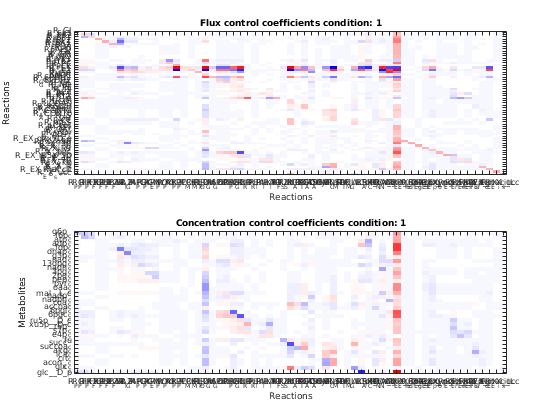

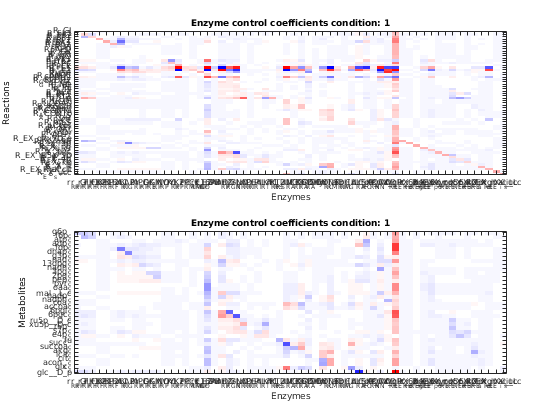

categories = {};         % Displays MCA results for all the reactions
plotControlAndResponseAnalysis(mcaResults, ensemble, categories);

toc

Elapsed time is 3140.894976 seconds.


To visualize the final results, one can also use the Jupyter notebook visualize_MCA in the visualization folder.